clear
close all
targetImage = im2double(imread("recreatedStarryNightMain1.png"));

oTileSize = 32;
[rows, cols, ~] = size(targetImage)

rows = 4544

cols = 6080

tileRows = ceil(rows / oTileSize)

tileRows = 142

tileCols = ceil(cols / oTileSize)

tileCols = 190


processbar = waitbar(0, 'Processing Images...');
addedImages = {};
r = 1;
c = 1;
tileRFrom = 1 + (r-1)*(oTileSize);
tileRTo = r*oTileSize;
tileCFrom = 1 + (c-1)*(oTileSize);
tileCTo = c*oTileSize;
currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
addedImages{1} = currentTile;
tic
% go through each tile
for c = 1:1:tileCols
    waitbar(c/tileCols, processbar, "bonking kitties...");
    for r = 1:1:tileRows          
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
        addImage = true;
        [a, b] = size(addedImages);
        for i = 1:b       
            compareTile = addedImages{i};
            if currentTile == compareTile
                addImage = false;
                break    
            end
        end
        if addImage == true
            addedImages{end +1} = currentTile;
        end
    end
end
close(processbar)
[a, b] = size(addedImages)

a = 1

b = 71

Post processing

% S-CIELAB: Measures perceptual color differences with spatial filtering.
%scale output image to original size to comapre
outputImage = targetImage;
targetImage = im2double(imread("dogdogorange.png"));


outputImageResized = imresize(outputImage, size(targetImage(:,:,1)),"bicubic");

%check same size
disp(size(outputImageResized));

   867   701     3



disp(size(targetImage));

   867   701     3




outputImageXYZ = rgb2xyz(outputImageResized);
targetImageXYZ = rgb2xyz(targetImage);


%calc PPI
screenHeight = 1440; %pixels
screenWidth = 2560; %pixels
hypPix = hypot(screenWidth, screenHeight);
hypInch = 27; %diagonal size (inches)
ppi = hypPix / hypInch;

d = 16; % ~40 cm 
sampPerDeg = ppi * d * tan(pi/180); % spd = ppi * avstånd till bild i inches * tan(pi/180)
CIED65samp = [95.05, 100, 108.9];

%full reference metric
scielabVal = scielab(sampPerDeg, outputImageXYZ, targetImageXYZ, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



scielabAvg = mean(mean(scielabVal));
disp(['Average scielab value: ', num2str(scielabAvg)]);

Average scielab value: 1.2483


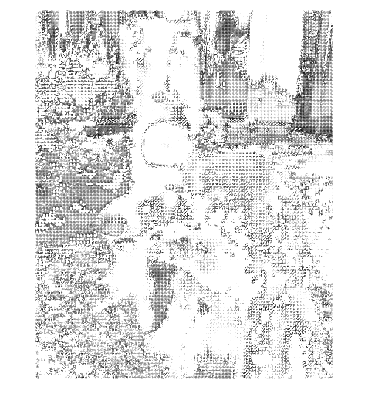

imshow(scielabVal)



% SSIM: Evaluates structural similarity based on luminance, contrast, and structure.
[dist2val, dist2map] = ssim(targetImage, outputImageResized);
disp(['SSIM Value: ', num2str(dist2val)]);

SSIM Value: 0.28983


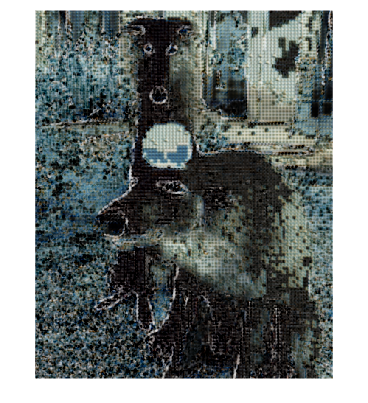

imshow(dist2map)

%imwrite(dist2map, 'dist2mapdark1nopre.png')

% PSNR: Quantifies the signal-to-noise ratio, useful for overall image fidelity.
psnrVal = psnr(targetImage, outputImageResized);
disp(['PSNR Value: ', num2str(psnrVal), ' dB']);

PSNR Value: 16.6403 dB
